# Assessment of CICE using the observations from Vichi et al. (2019).

## Preamble and set up

clear all
clc
close all
addpath functions

historydir = '/Users/noahday/GitHub/CICE-plotting-tools/cases/wim_day/history/';
sector = "vichi";
user = "noahday";
%'/Users/noahday/GitHub/CICE-plotting-tools/cases/monthwim/history/';
% '/Volumes/NoahDay5TB/cases/monthwim/history/';
a = dir([historydir '/*.nc']);
n_files = numel(a);

% Read in file names
for i = 1:n_files
   filenames(i,:) = strcat(historydir,a(i).name);
   dirdates(i,:) = a(i).name(6:end-3);
end
NFSD = ncread(filenames(1,:),"NFSD");
NCAT = ncread(filenames(1,:),"NCAT");

filedir = filenames(1,:);
variable = "aice";
% Get the info
info = ncinfo(filedir,variable);
attributes = info.Attributes;
coord_att = attributes(3); % Extract coordinate info
coord_string = coord_att.Value;
if coord_string(1:9) == 'TLON TLAT'
    coord_type = "t"; % T-grid
    coord_type = "t"; % T-grid
    lat = ncread(filedir,"TLAT");
    lon = ncread(filedir,"TLON");
elseif coord_string(1:9) == 'ULON ULAT'
    coord_type = "u"; % U-grid
    lat = ncread(filedir,"ULAT");
    lon = ncread(filedir,"ULON");
else
    error('ND: Unspecified grid type');
end
data_size = info.Size;
idx = (data_size == 1);
dim = length(data_size(~idx));
if data_size(1) == 320 && data_size(2) == 384
    grid = "gx1";
    row = 37;
    lat = rearrange_matrix(lat,row,2);
    lon = rearrange_matrix(lon,row,2);

    lon = [zeros(1,384);lon];
    lat = [lat(1,:); lat];
else
    error('ND: Unrecognised grid size.')
end

## Figure 1.

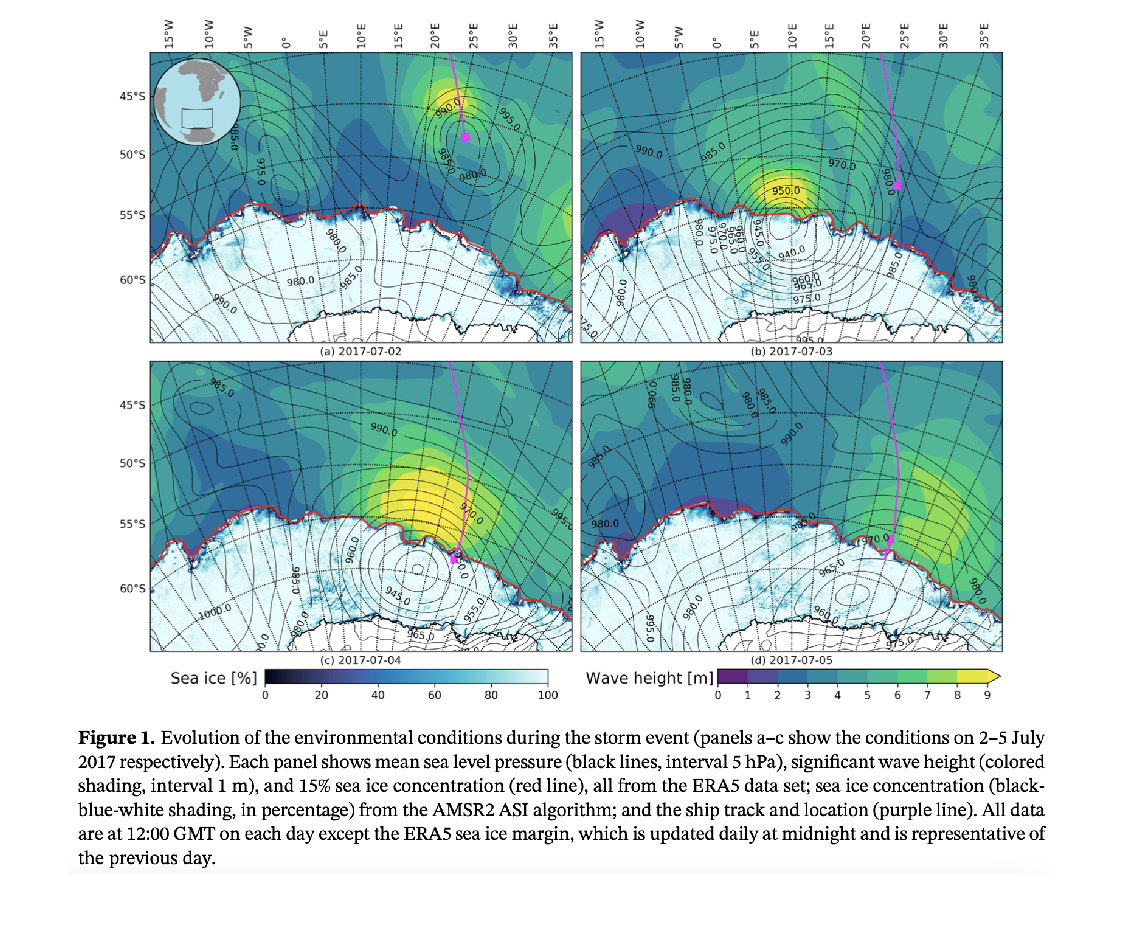

f1 = figure;
imshow(imread("observations/vichi_2019/fig1.png"))

What do we need to replicate these results?

- Ice concentration, `aice`

- Significant wave height, `wave_sig_ht`

- Sea level pressure, `unknown`

% Get this data
SIC = 0.15;
sector = "SH"

sector = "SH"

for i = 1:n_files
    temp = data_format_sector(filenames(i,:),"aice",sector);
    ice_mask(:,:,i) = temp > 0.01;
    %temp_mask = temp > 0.01;
    temp(~ice_mask(:,:,i)) = NaN;
    aice(:,:,i) = temp;
    swh(:,:,i) = data_format_sector(filenames(i,:),"wave_sig_ht",sector);
end

% sector = "vichi2"
% for i = 1:n_files
%     aice2(:,:,i) = data_format_sector(filenames(i,:),"aice",sector);
%     aice(:,:,i) = aice(:,:,i) + aice2(:,:,i);
%     ice_mask2(:,:,i) = aice(:,:,i) > SIC;
%     swh2(:,:,i) = data_format_sector(filenames(i,:),"wave_sig_ht",sector);
% end



sector = "vichi"

sector = "vichi"

coords = sector_coords(sector)

coords =    -40   345
   -65   345
   -40    40
   -65    40


for i = 1:4
    [lat_out(i),lon_out(i)] = lat_lon_finder(coords(i,1),coords(i,2),lat,lon);
end

% Replicate Figure 1a.
f_aice = figure;
[w, a, output_data] = map_plot(aice(:,:,1),"aice","vichi"); % 7 Means average from July
cmocean('ice',10)

f_swh = figure;
map_plot(swh(:,:,1),"wave_sig_ht","vichi");
cmocean('thermal',10)

% ND: include the waves from CAWCR hindcast around the ice?

## Figure S4.

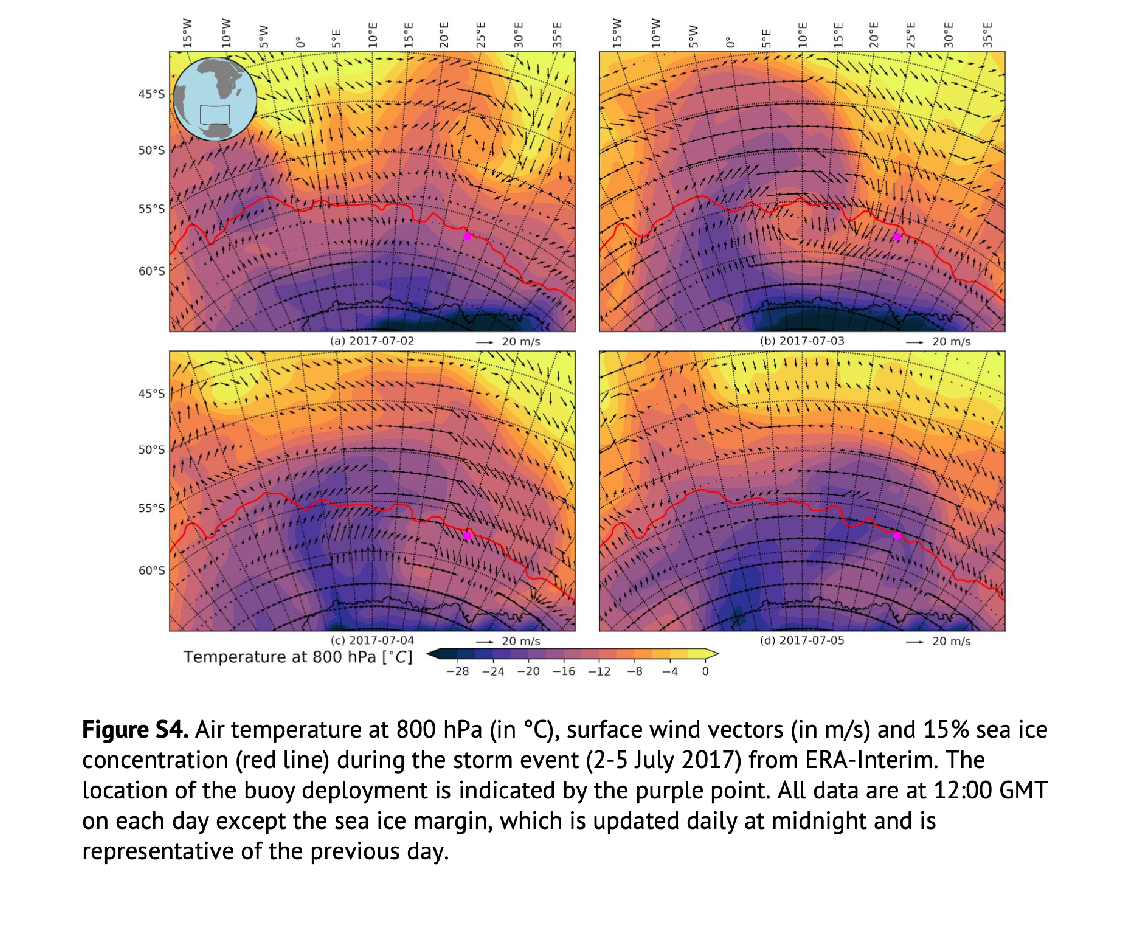

s4 = figure;
imshow(imread("observations/vichi_2019/figs4.png"))

What do we need to replicate these results?

- Ice edge, `aice`

- Air temperature, `wave_sig_ht`

- Sea level pressure, `unknown`

% Get this data
SIC = 0.15;
sector = "SH"

sector = "SH"

for i = 1:n_files
    temp = data_format_sector(filenames(i,:),"aice",sector);
    ice_mask(:,:,i) = temp > 0.01;
    %temp_mask = temp > 0.01;
    temp(~ice_mask(:,:,i)) = NaN;
    aice(:,:,i) = temp;
    air_temp(:,:,i) = data_format_sector(filenames(i,:),"Tair",sector); % Celsius
    air_u(:,:,i) = data_format_sector(filenames(i,:),"uatm",sector); % m/s
    air_v(:,:,i) = data_format_sector(filenames(i,:),"vatm",sector); % m/s
    ice_u(:,:,i) = data_format_sector(filenames(i,:),"uvel",sector); % m/s
    ice_v(:,:,i) = data_format_sector(filenames(i,:),"vvel",sector); % m/s
    daidtd(:,:,i) = data_format_sector(filenames(i,:),"daidtd",sector); % area tendency dynamics, %/day
    daidtt(:,:,i) = data_format_sector(filenames(i,:),"daidtt",sector); % area tendency thermo,%/day
    dvidtt(:,:,i) = data_format_sector(filenames(i,:),"dvidtt",sector); % volume tendency thermo, %/day
    dvidtd(:,:,i) = data_format_sector(filenames(i,:),"dvidtd",sector); % volume tendency dynamimcs, %/day
    sst(:,:,i) = data_format_sector(filenames(i,:),"sst",sector); % sea suface temp, degrees C
end

% Replicate Figure S4a.
f_air = figure;
month = 1;
lat_vec = reshape(lat,[],1);
lon_vec = reshape(lon,[],1);
air_vec = [reshape(air_u(:,:,month),[],1), reshape(air_v(:,:,month),[],1)];
[lat_ice_edge, lon_ice_edge, edge] = find_ice_edge(aice(:,:,month),SIC,sector,lat,lon);
[w, a, output_data] = map_plot(air_temp(:,:,month),"aice","vichi"); % 7 Means average from July
quivermc(lat,lon,air_u(:,:,month),air_v(:,:,month),'density',100,'units','Wind [m/s]','reference',10)

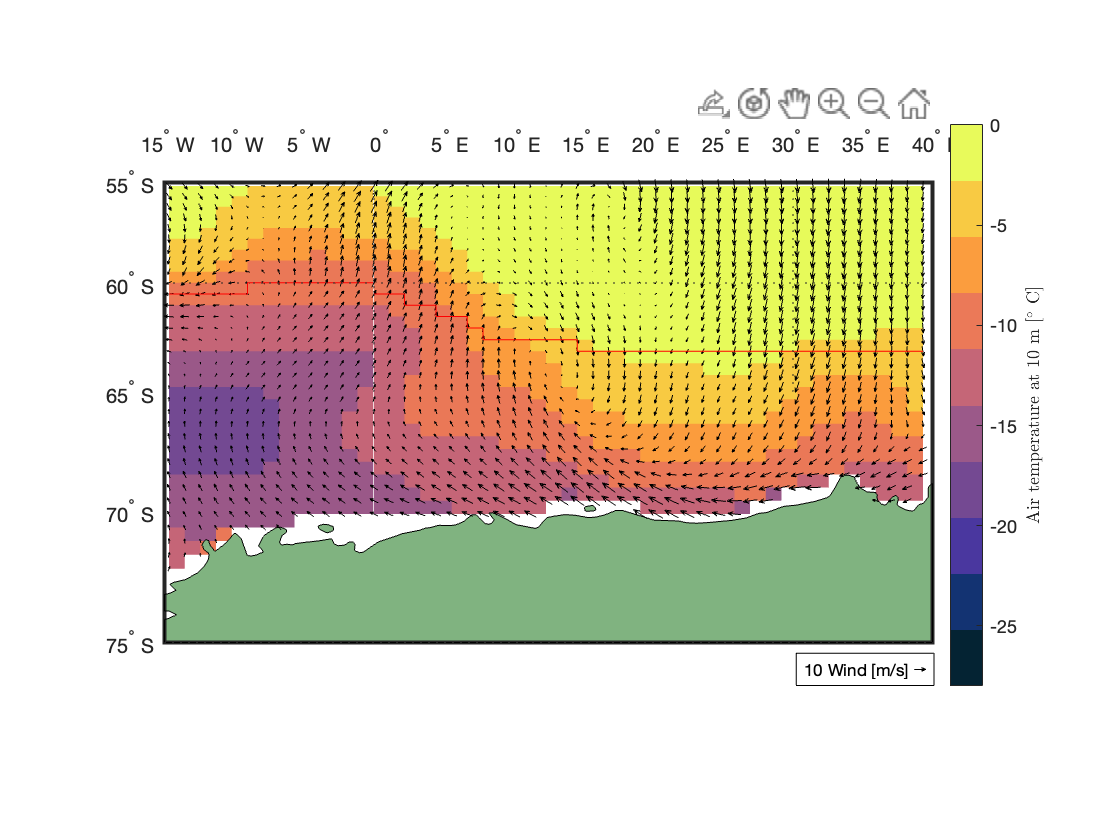

plotm(lat_ice_edge,lon_ice_edge,'k') %lat_vec,lon_vec,
cmocean('thermal',10)
a.Label.String = "Air temperature at 10 m [$^\circ$ C]";
a.Label.Interpreter = "latex";
caxis([-28,0]);


% Now let's plot how the ice velocity responds in this situation

f_ice = figure;
month = 6;
lat_vec = reshape(lat,[],1);
lon_vec = reshape(lon,[],1);
air_vec = [reshape(air_u(:,:,month),[],1), reshape(air_v(:,:,month),[],1)];

Index in position 3 exceeds array bounds. Index must not exceed 4.

[lat_ice_edge, lon_ice_edge, edge] = find_ice_edge(aice(:,:,month),SIC,sector,lat,lon);
[w, a, output_data] = map_plot(air_temp(:,:,month),"aice","vichi"); % 7 Means average from July
quivermc(lat,lon,ice_u(:,:,month),ice_v(:,:,month),'density',100,'units','Ice drift [m/s]','reference',0.2)
plotm(lat_ice_edge,lon_ice_edge,'k') %lat_vec,lon_vec,
cmocean('thermal',10)
a.Label.String = "Air temperature at 10 m [$^\circ$ C]";
a.Label.Interpreter = "latex";
caxis([-28,0]);


## Figure 3.

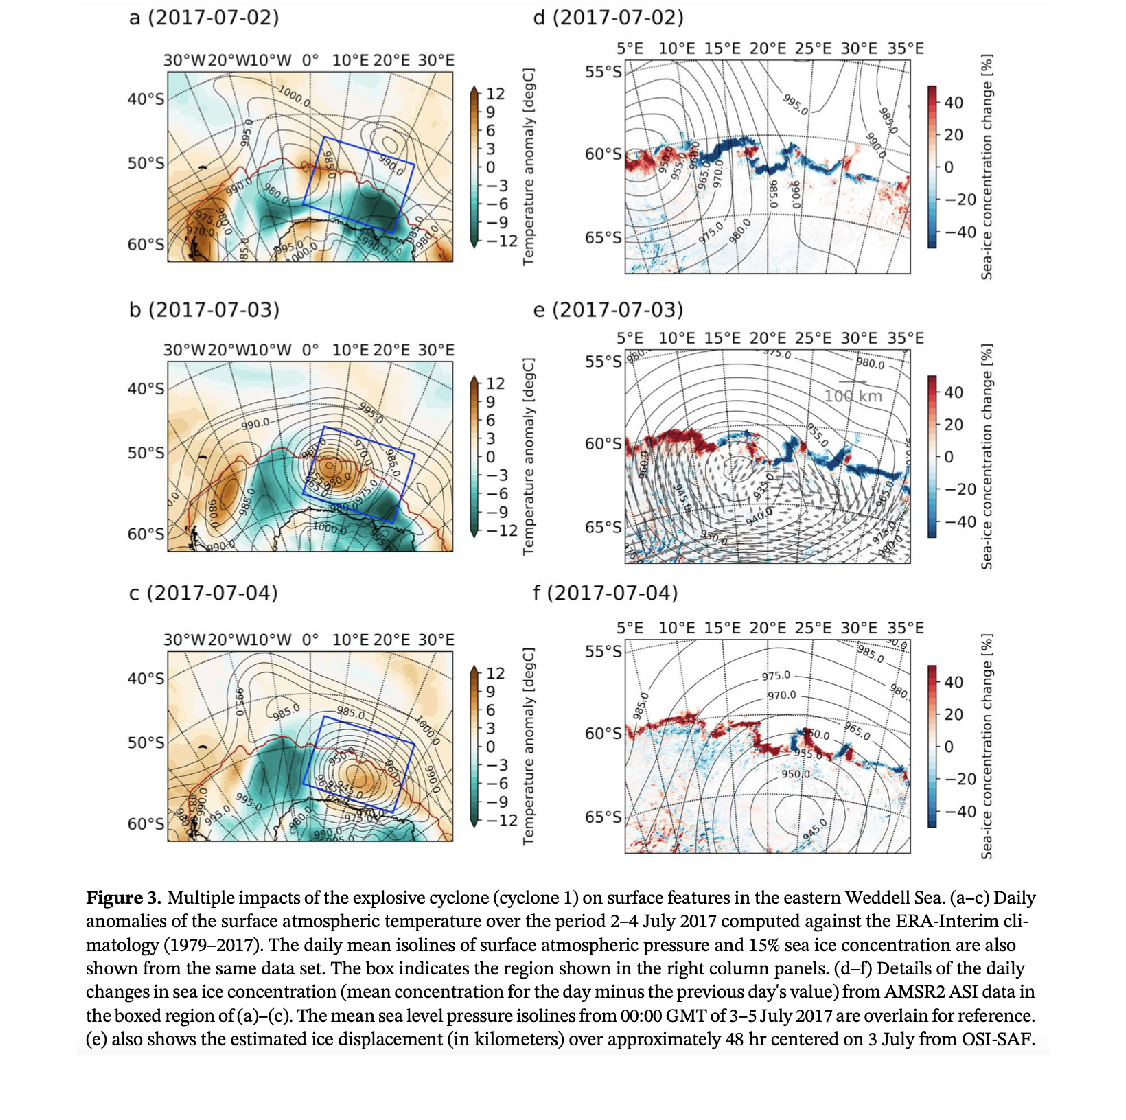

f3 = figure;
imshow(imread("observations/vichi_2019/fig3.png"))

What do we need to replicate these results?

- Ice concentration, `aice`

% Change in ice concentration
aice_change(:,:,1) = aice(:,:,1) -  aice(:,:,1);
for i = 1:n_files-1
    aice_change(:,:,i+1) = (aice(:,:,i+1) -  aice(:,:,i))*100; % 100 for percent
end

clear month
f_dice = figure;
sector = "vichi3";
col_bins = 11;
t = tiledlayout(3,1)

t =   TiledChartLayout with properties:

    TileArrangement: 'fixed'
           GridSize: [3 1]
            Padding: 'loose'
        TileSpacing: 'loose'

  Show all properties


t.TileSpacing = "compact";
nexttile
day = 2;
lat_vec = reshape(lat,[],1);
lon_vec = reshape(lon,[],1);
air_vec = [reshape(air_u(:,:,day),[],1), reshape(air_v(:,:,day),[],1)];
[lat_ice_edge, lon_ice_edge, edge] = find_ice_edge(aice(:,:,day),SIC,sector,lat,lon);
[w, a, output_data] = map_plot(aice_change(:,:,day),"aice",sector); % 7 Means average from July
quivermc(lat,lon,ice_u(:,:,day),ice_v(:,:,day),'density',100,'units','Ice drift [m/s]','reference',0.5)

plotm(lat_ice_edge,lon_ice_edge,'g') %lat_vec,lon_vec,
cmocean('balance',col_bins)
a.Label.String = "Change in ice concentration per day [$\%$]";
a.Label.Interpreter = "latex";
caxis([-50,50]);
title('2008-07-02')
nexttile
day = 3;
lat_vec = reshape(lat,[],1);
lon_vec = reshape(lon,[],1);
air_vec = [reshape(air_u(:,:,day),[],1), reshape(air_v(:,:,day),[],1)];
[lat_ice_edge, lon_ice_edge, edge] = find_ice_edge(aice(:,:,day),SIC,sector,lat,lon);
[w, a, output_data] = map_plot(aice_change(:,:,day),"aice",sector); % 7 Means average from July
quivermc(lat,lon,ice_u(:,:,day),ice_v(:,:,day),'density',100,'units','Ice drift [m/s]','reference',0.5)

plotm(lat_ice_edge,lon_ice_edge,'g') %lat_vec,lon_vec,
cmocean('balance',col_bins)
a.Label.String = "Change in ice concentration per day [$\%$]";
a.Label.Interpreter = "latex";
caxis([-50,50]);
title('2008-07-03')
nexttile
day = 4;
lat_vec = reshape(lat,[],1);
lon_vec = reshape(lon,[],1);
air_vec = [reshape(air_u(:,:,day),[],1), reshape(air_v(:,:,day),[],1)];
[lat_ice_edge, lon_ice_edge, edge] = find_ice_edge(aice(:,:,day),SIC,sector,lat,lon);
[w, a, output_data] = map_plot(aice_change(:,:,day),"aice",sector); % 7 Means average from July
quivermc(lat,lon,ice_u(:,:,day),ice_v(:,:,day),'density',100,'units','Ice drift [m/s]','reference',0.5)

plotm(lat_ice_edge,lon_ice_edge,'g') %lat_vec,lon_vec,
cmocean('balance',col_bins)
a.Label.String = "";
a.Label.Interpreter = "latex";
caxis([-50,50]);

% title('2008-07-04')
%exportgraphics(f_dice,'change_in_SIC.pdf','ContentType','vector')

% daidtd
f_daidtd = figure;
sector = "vichi3";
col_bins = 11;
t = tiledlayout(3,1)

t =   TiledChartLayout with properties:

    TileArrangement: 'fixed'
           GridSize: [3 1]
            Padding: 'loose'
        TileSpacing: 'loose'

  Show all properties


t.TileSpacing = "compact";
nexttile
day = 2;
[lat_ice_edge, lon_ice_edge, edge] = find_ice_edge(aice(:,:,day),SIC,sector,lat,lon);
[w, a, output_data] = map_plot(daidtd(:,:,day),"aice",sector); % 7 Means average from July
quivermc(lat,lon,ice_u(:,:,day),ice_v(:,:,day),'density',100,'units','Ice drift [m/s]','reference',0.5)

plotm(lat_ice_edge,lon_ice_edge,'g') %lat_vec,lon_vec,
cmocean('balance',col_bins)
a.Label.String = "area tendency dynamics [$\%$/day]";
a.Label.Interpreter = "latex";
caxis([-50,50]);
title('2008-07-02')

nexttile
day = 3;
[lat_ice_edge, lon_ice_edge, edge] = find_ice_edge(aice(:,:,day),SIC,sector,lat,lon);
[w, a, output_data] = map_plot(daidtd(:,:,day),"aice",sector); % 7 Means average from July
quivermc(lat,lon,ice_u(:,:,day),ice_v(:,:,day),'density',100,'units','Ice drift [m/s]','reference',0.5)

plotm(lat_ice_edge,lon_ice_edge,'g') %lat_vec,lon_vec,
cmocean('balance',col_bins)
a.Label.String = "area tendency dynamics [$\%$/day]";
a.Label.Interpreter = "latex";
caxis([-50,50]);
title('2008-07-03')

nexttile
day = 4;
[lat_ice_edge, lon_ice_edge, edge] = find_ice_edge(aice(:,:,day),SIC,sector,lat,lon);
[w, a, output_data] = map_plot(daidtd(:,:,day),"aice",sector); % 7 Means average from July
quivermc(lat,lon,ice_u(:,:,day),ice_v(:,:,day),'density',100,'units','Ice drift [m/s]','reference',0.5)

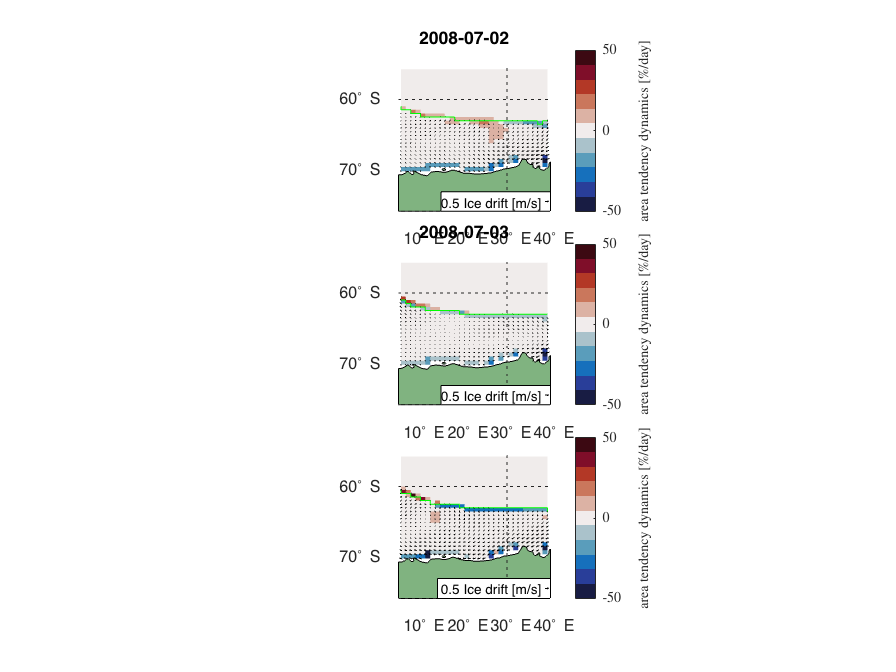

plotm(lat_ice_edge,lon_ice_edge,'g') %lat_vec,lon_vec,
cmocean('balance',col_bins)
a.Label.String = "area tendency dynamics [$\%$/day]";
a.Label.Interpreter = "latex";
caxis([-50,50]);

% title('2008-07-04')
%exportgraphics(f_dice,'daidtd.pdf','ContentType','vector')


% daidtt
lat_vec = reshape(lat,[],1);
lon_vec = reshape(lon,[],1);


f_daidtt = figure;
sector = "vichi3";
col_bins = 11;
t = tiledlayout(3,2)

t =   TiledChartLayout with properties:

    TileArrangement: 'fixed'
           GridSize: [3 2]
            Padding: 'loose'
        TileSpacing: 'loose'

  Show all properties


t.TileSpacing = "compact";
t.Padding = "compact";
nexttile
day = 2;
air_vec = [reshape(air_u(:,:,day),[],1), reshape(air_v(:,:,day),[],1)];
[w, a, output_data] = map_plot(air_temp(:,:,day),"aice",sector); % 7 Means average from July
quivermc(lat,lon,air_u(:,:,day),air_v(:,:,day),'density',100,'units','Wind [m/s]','reference',10)

plotm(lat_ice_edge,lon_ice_edge,'k') %lat_vec,lon_vec,
cmocean('thermal',10)
a.Label.String = "Air temperature at 10 m [$^\circ$ C]";
a.Label.Interpreter = "latex";
caxis([-28,0]);
nexttile
[lat_ice_edge, lon_ice_edge, edge] = find_ice_edge(aice(:,:,day),SIC,sector,lat,lon);
[w, a, output_data] = map_plot(daidtt(:,:,day),"aice",sector); % 7 Means average from July
quivermc(lat,lon,ice_u(:,:,day),ice_v(:,:,day),'density',100,'units','Ice drift [m/s]','reference',0.5)

plotm(lat_ice_edge,lon_ice_edge,'g') %lat_vec,lon_vec,
cmocean('balance',col_bins)
a.Label.String = "area tendency thermo [$\%$/day]";
a.Label.Interpreter = "latex";
caxis([-50,50]);
title('2008-07-02')


nexttile
day = 3;
air_vec = [reshape(air_u(:,:,day),[],1), reshape(air_v(:,:,day),[],1)];
[w, a, output_data] = map_plot(air_temp(:,:,day),"aice",sector); % 7 Means average from July
quivermc(lat,lon,air_u(:,:,day),air_v(:,:,day),'density',100,'units','Wind [m/s]','reference',10)

plotm(lat_ice_edge,lon_ice_edge,'k') %lat_vec,lon_vec,
cmocean('thermal',10)
a.Label.String = "Air temperature at 10 m [$^\circ$ C]";
a.Label.Interpreter = "latex";
caxis([-28,0]);
nexttile
[lat_ice_edge, lon_ice_edge, edge] = find_ice_edge(aice(:,:,day),SIC,sector,lat,lon);
[w, a, output_data] = map_plot(daidtt(:,:,day),"aice",sector); % 7 Means average from July
quivermc(lat,lon,ice_u(:,:,day),ice_v(:,:,day),'density',100,'units','Ice drift [m/s]','reference',0.5)

plotm(lat_ice_edge,lon_ice_edge,'g') %lat_vec,lon_vec,
cmocean('balance',col_bins)
a.Label.String = "area tendency thermo [$\%$/day]";
a.Label.Interpreter = "latex";
caxis([-50,50]);
title('2008-07-03')

nexttile
day = 4;
air_vec = [reshape(air_u(:,:,day),[],1), reshape(air_v(:,:,day),[],1)];
[w, a, output_data] = map_plot(air_temp(:,:,day),"aice",sector); % 7 Means average from July
quivermc(lat,lon,air_u(:,:,day),air_v(:,:,day),'density',100,'units','Wind [m/s]','reference',10)

plotm(lat_ice_edge,lon_ice_edge,'k') %lat_vec,lon_vec,
cmocean('thermal',10)
a.Label.String = "Air temperature at 10 m [$^\circ$ C]";
a.Label.Interpreter = "latex";
caxis([-28,0]);
nexttile
[lat_ice_edge, lon_ice_edge, edge] = find_ice_edge(aice(:,:,day),SIC,sector,lat,lon);
[w, a, output_data] = map_plot(daidtt(:,:,day),"aice",sector); % 7 Means average from July
quivermc(lat,lon,ice_u(:,:,day),ice_v(:,:,day),'density',100,'units','Ice drift [m/s]','reference',0.5)

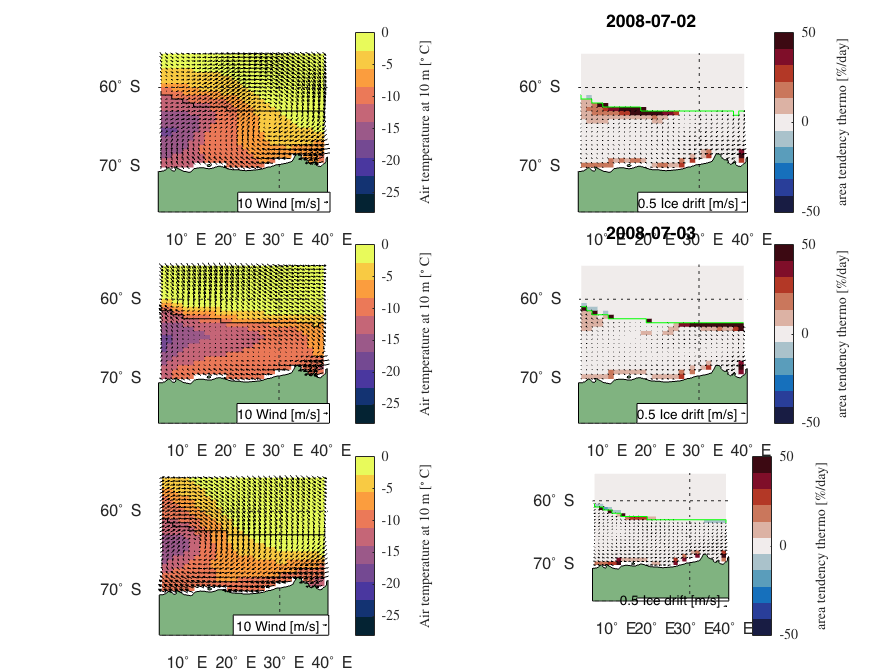

plotm(lat_ice_edge,lon_ice_edge,'g') %lat_vec,lon_vec,
cmocean('balance',col_bins)
a.Label.String = "area tendency thermo [$\%$/day]";
a.Label.Interpreter = "latex";
caxis([-50,50]);

% title('2008-07-04')
%exportgraphics(f_dice,'daidtd.pdf','ContentType','vector')